clear; clc; close all;

digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', ...
    'nndatasets', 'DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    "IncludeSubfolders", true, 'LabelSource', 'foldernames');

img = readimage(imds, 3000);
size(img)

ans =     28    28


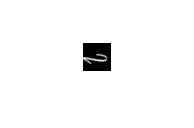

imshow(img)

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.6, 'randomized')

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9005.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9006.png'
                               ... and 5997 more
                              }
                     Folders: {
                              ' ...\Matlab2023a\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 5997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                    

imdsValidation =   ImageDatastore with properties:

                       Files: {
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9003.png'
                               ... and 3997 more
                              }
                     Folders: {
                              ' ...\Matlab2023a\R2023a\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 3997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
              

layers = [
imageInputLayer([28 28 1], "Normalization", "rescale-zero-one")
convolution2dLayer(3, 32, "Padding", "same")
reluLayer
maxPooling2dLayer(2)
convolution2dLayer(3, 64, "Padding", "same")
reluLayer
maxPooling2dLayer(2)
fullyConnectedLayer(10)
softmaxLayer
classificationLayer
];

options = trainingOptions("sgdm", "InitialLearnRate", 0.01, "MaxEpochs", 4, "Shuffle", "every-epoch", "Plots","training-progress")
net = trainNetwork(imdsTrain, layers, options)

YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred==YValidation)/numel(YValidation)